### Set Up

clear; close all
load BigNetworkExperimentsBetaSkeleton.mat

s = zeros(numNode,1);
dNode = 1000;
s(oNode)=1;
s(dNode)=-1;

B=zeros(numNode,numEdge);
listEdge = (1:numEdge)';
sNode = G.Edges.EndNodes(:,1);
tNode = G.Edges.EndNodes(:,2);
B(sub2ind(size(B), sNode, listEdge)) = 1;
B(sub2ind(size(B), tNode, listEdge)) = -1;

###  Show graphically how the network ‘fills up’ as demand d is increased from 0

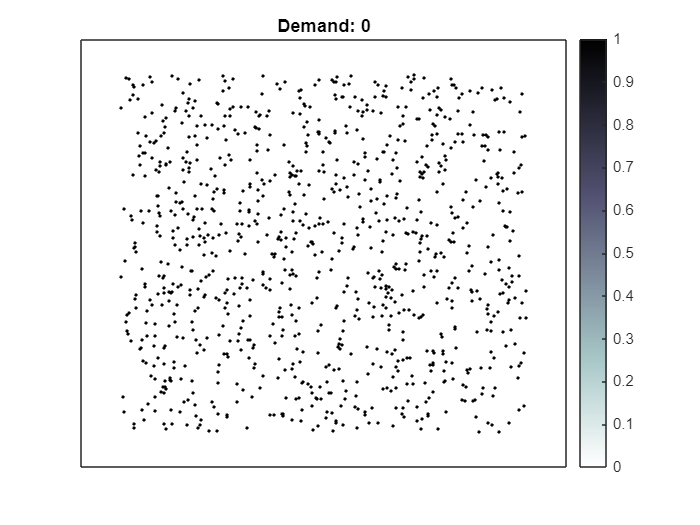

Unused Edges: 1895, Edges with Flow < 0.001: 1895, Edges with Flow < 0.5: 1895


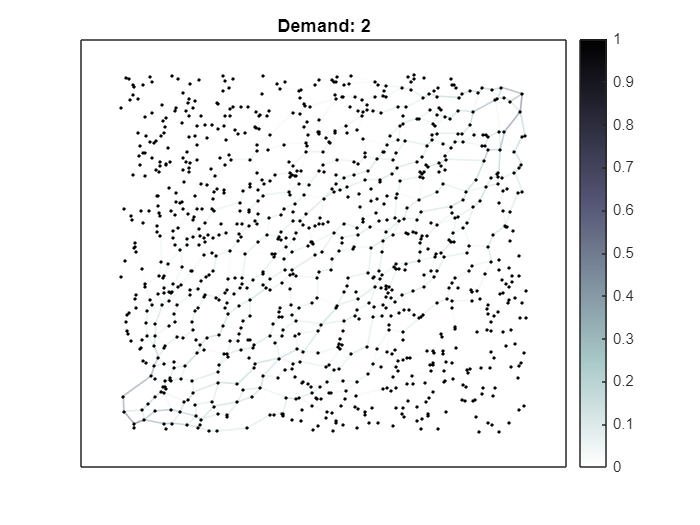

Unused Edges: 280, Edges with Flow < 0.001: 937, Edges with Flow < 0.5: 1253


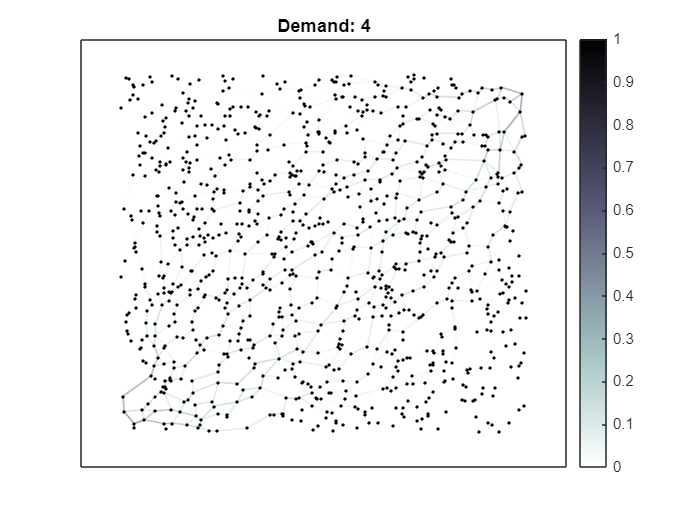

Unused Edges: 280, Edges with Flow < 0.001: 795, Edges with Flow < 0.5: 1002


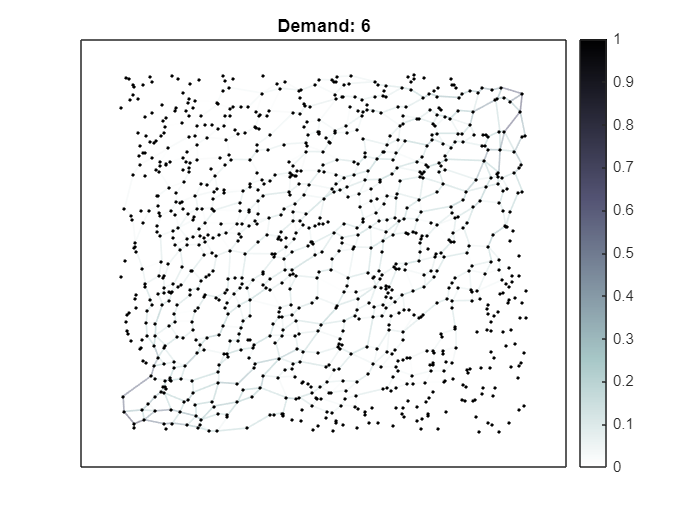

Unused Edges: 280, Edges with Flow < 0.001: 721, Edges with Flow < 0.5: 879


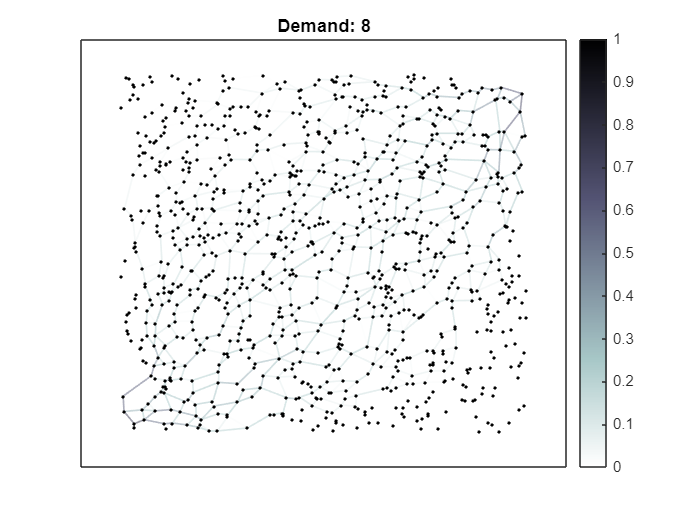

Unused Edges: 280, Edges with Flow < 0.001: 669, Edges with Flow < 0.5: 813
Unused Edges: 280, Edges with Flow < 0.001: 636, Edges with Flow < 0.5: 754


% Parameters
dValues = 0:2:10;  % Demand levels from 0 to 100 in steps of 20
linkFlows = zeros(numEdge, length(dValues)); % Preallocate space for storing link flows
Aeq = B;                % Node conservation matrix
A = [];                 % No inequality constraints
bvec = [];              % No inequality constraints
LB = zeros(numEdge, 1); % Lower bound for link flows
UB = [];                % No upper bounds

for i = 1:length(dValues)
    d = dValues(i);
    beq = d * s;        % Scale the demand vector
    H = diag(b);        % Quadratic term for the Beckmann functional
    f = a;              % Linear term

    % Solve the User Equilibrium problem using quadprog
    [x, fval, exitflag] = quadprog(H, f, A, bvec, Aeq, beq, LB, UB);

    % Store the link flows
    linkFlows(:, i) = x;
    numZeros = sum(x == 0);
    num0001 = sum(x < 0.001);
    num05 = sum(x < 0.05);

    % Plot the network
    % subplot(numRows, numCols, i); 
    figure(i);
    ax=axes;
    plotNetwork(G, x, nodeCoordinates, ax);  % custom function for plotting
    % xlabel('X Coordinates');
    % ylabel('Y Coordinates');
    title(['Demand: ', num2str(d)]);
    pause(0.1);
    disp(['Unused Edges: ', num2str(numZeros), ', Edges with Flow < 0.001: ', num2str(num0001), ', Edges with Flow < 0.5: ', num2str(num05)]);
    pause(0.1);
end

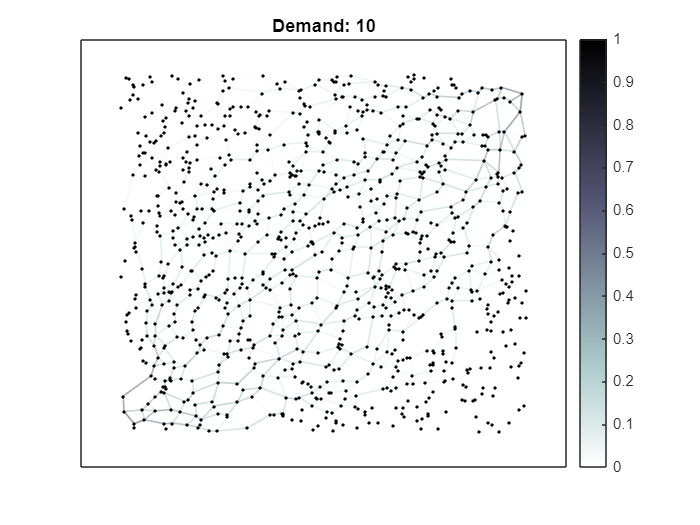

hold off;

function plotNetwork(G, x, nodeCoordinates, ax)
    % G is the graph object
    % x is the vector of link flows
    % nodeCoordinates is a 1000x2 matrix with the (x, y) positions of the nodes

    constantLineWidth = 1; 
    p = plot(ax, G, 'LineWidth', constantLineWidth);
    p.XData = nodeCoordinates(:, 1);  % X-coordinates
    p.YData = nodeCoordinates(:, 2);  % Y-coordinates
    p.NodeColor = [0, 0, 0]; 
    p.MarkerSize = 1;

    % Normalize flow values
    flowNormalized = log10(x + 1);  % +1 to avoid log(0) if there are zero flows
    flowNormalized = flowNormalized / max(flowNormalized); 
    p.EdgeCData = flowNormalized;  % Assign the edge color data
    
    % Apply colour map
    colormap('bone');
    colormap(flipud(colormap));  % Reverse the  colormap
    colorbar; 
    clim([0 1]);  % Set the color scale to match normalized flow values (0 to 1)

    axis tight;
end